# Control a Simulated UAV Using ROS 2 and PX4 Bridge

This example demonstrates how to receive sensor readings and autopilot status from a simulated UAV with PX4® autopilot, and send control commands to navigate the simulated UAV.  

## Set Up Simulation Environment

In MATLAB®, generate custom messages for the `px4_msgs` package. You can add this to an existing custom message folder and regenerate it, or generate them in this example folder. This can take some time, as there are a large number of messages to generate.

The message definitions in the `px4_msgs` package must be compatible with the ROS 2 version used. This example is tested with PX4 v1.14 in ROS 2 Humble Hawksbill. For other compatible versions, see [ROS 2 Message Definitions for PX4](https://github.com/PX4/px4_msgs).

Download and connect to the virtual machine (VM) using instructions in [Get Started with Gazebo and Simulated TurtleBot](docid:ros_ug#mw_9c45a664-ab3d-48a5-a65a-52913b8532b5). On the VM, start the simulator and PX4 Bridge by clicking the "Gazebo PX4 SITL" desktop shortcut. This brings up a simple simulator of a quadrotor in Gazebo.

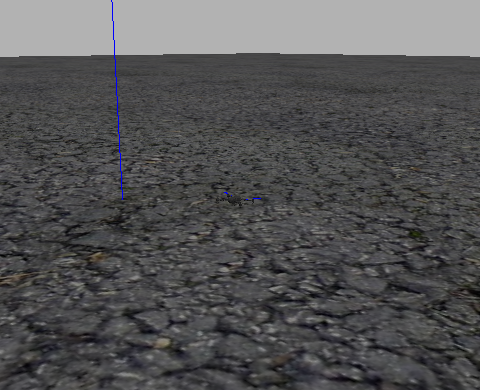

This also brings up the *Agent* half of the `microRTPS` bridge. The *Client* half of the communication is included in the PX4 Autopilot packages, and launches with the simulator.

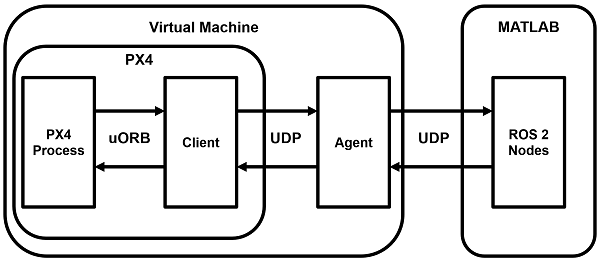

You can enter PX4 commands on the terminal corresponding to the Gazebo simulation, but that is not required for this example.

## Set Up ROS 2 Network

View the available topics that are broadcast by the bridge Agent. Notice the convention it uses to indicate the topics it is publishes to (`out`) and those it is subscribing to (`in`).

ros2 topic list

/LaserScan/out
/clock
/fmu/collision_constraints/out
/fmu/debug_array/in
/fmu/debug_key_value/in
/fmu/debug_value/in
/fmu/debug_vect/in
/fmu/offboard_control_mode/in
/fmu/onboard_computer_status/in
/fmu/optical_flow/in
/fmu/position_setpoint/in
/fmu/position_setpoint_triplet/in
/fmu/sensor_combined/out
/fmu/telemetry_status/in
/fmu/timesync/in
/fmu/timesync/out
/fmu/trajectory_bezier/in
/fmu/trajectory_setpoint/in
/fmu/trajectory_waypoint/out
/fmu/vehicle_command/in
/fmu/vehicle_control_mode/out
/fmu/vehicle_local_position_setpoint/in
/fmu/vehicle_mocap_odometry/in
/fmu/vehicle_odometry/out
/fmu/vehicle_status/out
/fmu/vehicle_trajectory_bezier/in
/fmu/vehicle_trajectory_waypoint/in
/fmu/vehicle_trajectory_waypoint_desired/out
/fmu/vehicle_visual_odometry/in
/parameter_events
/rosout
/timesync_status


Create a node to handle the sensor input and control feedback for the UAV. Create subscribers for sensors and information of interest, and publishers to direct the UAV in offboard control mode.

node = ros2node("/control_node");

% General information about the UAV system
controlModePub = ros2publisher(node,"fmu/offboard_control_mode/in","px4_msgs/OffboardControlMode");
statusSub = ros2subscriber(node,"/fmu/vehicle_status/out","px4_msgs/VehicleStatus","Reliability","besteffort");
timeSub = ros2subscriber(node,"/timesync_status","px4_msgs/TimesyncStatus","Reliability","besteffort");

% Sensor and control communication
odomSub = ros2subscriber(node,"/fmu/vehicle_odometry/out","px4_msgs/VehicleOdometry","Reliability","besteffort");
setpointPub = ros2publisher(node,"fmu/trajectory_setpoint/in","px4_msgs/TrajectorySetpoint");
cmdPub = ros2publisher(node,"/fmu/vehicle_command/in","px4_msgs/VehicleCommand");

Get the system and component IDs from the UAV status. These help direct the commands to the UAV. This also ensures the UAV is up and running before moving into the control phase.

timeLimit = 5;
statusMsg = receive(statusSub,timeLimit);
receive(odomSub,timeLimit);
receive(timeSub,timeLimit);

## Test MATLAB Communication with Gazebo instance

Use the previously created publisher and subscriber to instruct the UAV to take off, fly to a new point, and then land. To perform offboard control, the UAV requires control messages to be flowing regularly (at least 2 Hz). Starting the control messages before engaging offboard mode is the easiest way to achieve this.

% Start flow of control messages
tStart = tic;
xyz = [0 0 -1]; % NED coordinates - negative Z is higher altitude
while toc(tStart) < 1
    publishOffboardControlMode(timeSub,controlModePub,"position")
    publishTrajectorySetpoint(timeSub,setpointPub,xyz)
    pause(0.1)
end

% Instruct the UAV to accept offboard commands
% Arm the UAV so it allows flying
engageOffboardMode(timeSub,cmdPub)
arm(timeSub,cmdPub)

% Navigate to a nearby location and hover there
while toc(tStart) < 21
    publishOffboardControlMode(timeSub,controlModePub,"position")
    publishTrajectorySetpoint(timeSub,setpointPub,xyz)
    pause(0.1)
end

% Land once complete
land(timeSub,cmdPub)

## Control UAV from Simulink

You can also control the UAV using the Simulink® model `ControlUAVUsingROS2`. The Simulink model includes four main subsystems: Arm, Offboard, Takeoff, and Waypoint following with obstacle avoidance.

open_system("ControlUAVUsingROS2.slx");

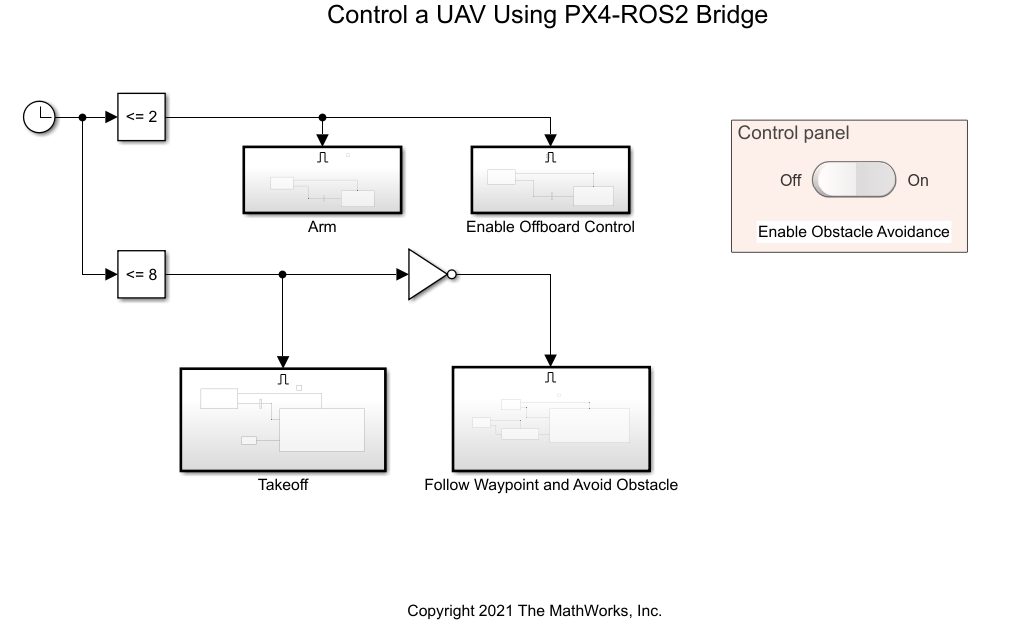

A Clock block triggers different UAV activity according to the simulation time. The model arms and enables the offboard control mode on the PX4 autopilot for the first 2 seconds. It sends out a takeoff command to bring the UAV to 1 meter above the ground for the first 8 seconds, then it engages in waypoint-following behavior.

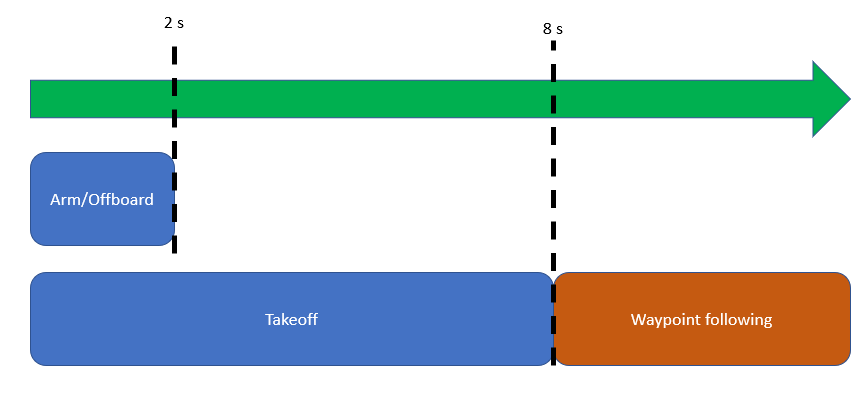

You can use the control panel to enable or disable the obstacle avoidance behavior. 

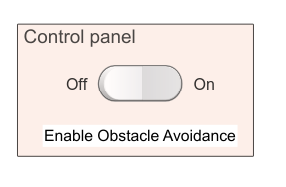

If obstacle avoidance is turned off, the UAV flies towards the goal point behind the obstacle box on a straight path, resulting in a collision. If obstacle avoidance is turned on, the UAV tries to fly above the obstacle based on the lidar sensor readings.

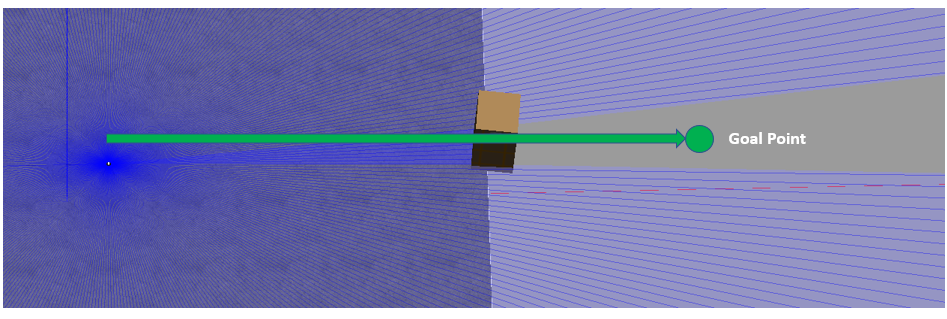

Once you start a fresh PX4-SITL and Gazebo instance in the VM, you can run the model and observe the flight behavior of the UAV.

## Helper Functions

function arm(timeSub,cmdPub)
% Allow UAV flight
    cmdMsg = ros2message(cmdPub);
    cmdMsg.command = uint32(cmdMsg.VEHICLE_CMD_COMPONENT_ARM_DISARM);
    cmdMsg.param1 = single(1);
    publishVehicleCommand(timeSub,cmdPub,cmdMsg)
end

function land(timeSub,cmdPub)
% Land the UAV
    cmdMsg = ros2message(cmdPub);
    cmdMsg.command = uint32(cmdMsg.VEHICLE_CMD_NAV_LAND);
    publishVehicleCommand(timeSub,cmdPub,cmdMsg)
end

function engageOffboardMode(timeSub,cmdPub)
% Allow offboard control messages to be utilized
    cmdMsg = ros2message(cmdPub);
    cmdMsg.command = uint32(cmdMsg.VEHICLE_CMD_DO_SET_MODE);
    cmdMsg.param1 = single(1);
    cmdMsg.param2 = single(6);
    publishVehicleCommand(timeSub,cmdPub,cmdMsg)
end

function publishOffboardControlMode(timeSub,controlModePub,controlType)
% Set the type of offboard control to be used
% controlType must match the field name in the OffboardControlMode message
    modeMsg = ros2message(controlModePub);
    modeMsg.timestamp = timeSub.LatestMessage.timestamp;
    % Initially set all to false
    modeMsg.position = false;
    modeMsg.velocity = false;
    modeMsg.acceleration = false;
    modeMsg.attitude = false;
    modeMsg.body_rate = false;
    % Override desired control mode to true
    modeMsg.(controlType) = true;
    send(controlModePub,modeMsg)
end

function publishTrajectorySetpoint(timeSub,setpointPub, xyz)

    setpointMsg = ros2message(setpointPub);
    setpointMsg.timestamp = timeSub.LatestMessage.timestamp;
    setpointMsg.x = single(xyz(1));
    setpointMsg.y = single(xyz(2));
    setpointMsg.z = single(xyz(3));
    send(setpointPub,setpointMsg)
end

function publishVehicleCommand(timeSub,cmdPub,cmdMsg)
    cmdMsg.timestamp = timeSub.LatestMessage.timestamp;
    cmdMsg.target_system = uint8(1);
    cmdMsg.target_component = uint8(1);
    cmdMsg.source_system = uint8(1);
    cmdMsg.source_component = uint8(1);
    cmdMsg.from_external = true;
    send(cmdPub,cmdMsg)
end

Copyright 2021 The MathWorks, Inc.